# **OFDM Receiver with Coding**

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

load svm_model.mat SVMModel
% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 3e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e5;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "5/6";   % Code rate
dataParams.numSymPerFrame = 25;   % Number of data symbols per frame
dataParams.numFrames      = 25;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx.` Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

centerFrequency        = 865.001e6;   % Center Frequency
gain                   = 40;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the paramters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 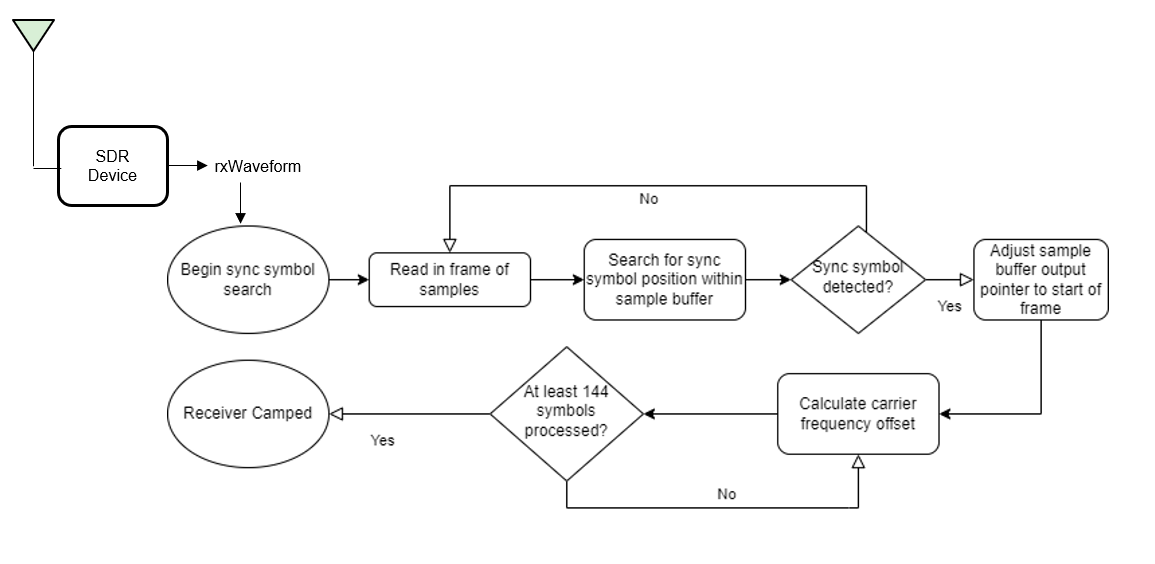

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

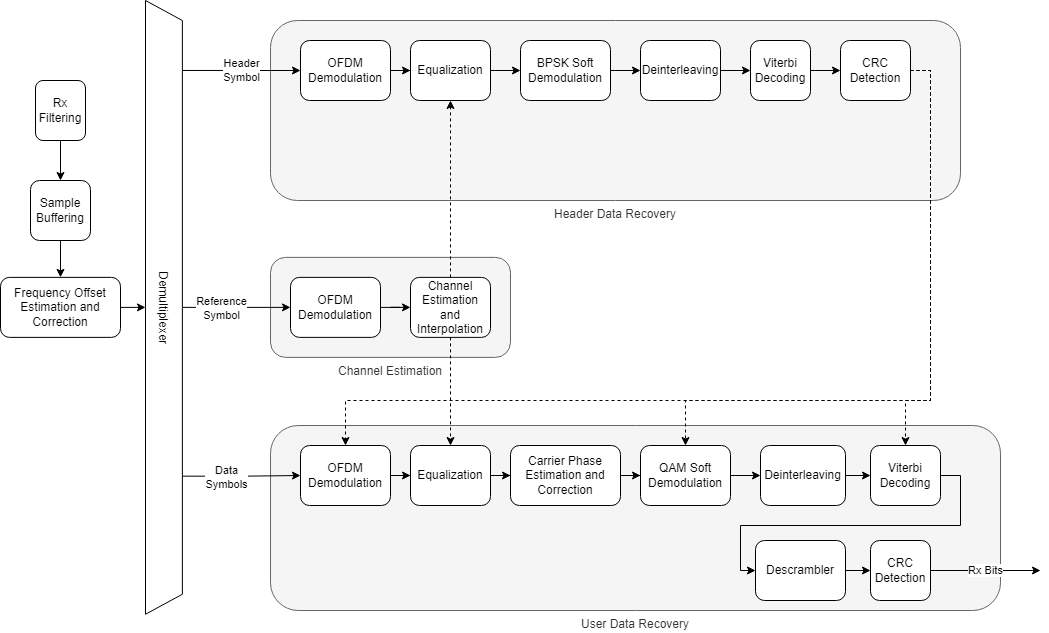

## Establishing connection to hardware. This process can take several seconds.


BER = 0 



Sync symbol found.
Estimating carrier frequency offset ...

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 



Receiver camped.


BER = 5.000000e-01 


Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.735828e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 10: Hei□j□H2O□□X□A?□
□□□_ry|40*S□□f	□f!\N□□D□□X]sg@□D.q{□1□=□nvYBu1: kz;□;~&zin□o}|]24"□}\7-LAT□Vp,o^})MW6+aSC □□JT
SJ bw?V□□%v□IB/LB!□Mt□rI□&)Oh6□J+□ H+3D□'3NV□n□3q□;MMy B(-J□3g"%□"□0D$wCUY><BF5nN□_□=t
b□□?□□~D□YC□"3EYO}D□	7_□□IM_/Ol:#ZiM'^F*yj□DTellls'orld!#Y□biL%$I□&)I^ {□□□U□□5|d#t□V□=
rK9a\d!&u!.^h}8p□XU□ ,ello□□R6□□V□□pywml&zk=
□[A4
	I@□Lm4d!!Ky/p1~" □4□1□FD"CWj□d□ytn3j□□!.□\%?-d7,<1_□8N
□J&)`
□
□2□fcVq(0M*~`□gf	□□a\N□@□]lh<□E\6+□x□Hyc_0ZQvx`Wm@4y+Mtp:&)a w□□+X□j+N=+Om□/*STstf#□KC□□□c□[LD
R*X^]&!/ V□□□IuLCi□□+Mb8/Q
□□(ello WDm1P□abeluo$World! HV?O,hd2B□s|□n□ll0}>e?-M4/]>Z7g□□□4S^[[$□eE;d
!□#m	M□8V	□=|Ld! Hello Wor|d) ILb:| Wh{E<! Hg□*P□^zin5E.Z□*Zjb□^gu□V)K□*S_
J[Ko{□78eIJ□u~=}1YeH8"{0J*□[N□□S(□Sll:)~8:&)a%□G9`□ThU:Fvr□g□~5□]<□?(□QRD□;@IL](p□d! HK9OvyX□□+t! He7C□T□+□yh+
□Z\lo V!.iYH"~e8y`□j"G□w□Tn'8_□vDZgv}]x□j L□	Yv□□□&d%$llo Wo'(□V□n□:*V□=!BiN8_□□ZW□fwO{po&=!□□U!|
□7□	□p~8J□ KaXWZq□1llo Wau+g?C+R
□funH0□□□□□W>MLerFK/□□= N#-□*hW□Mv{.;□Lc52;|□s.□{□UWor>fZr□

BER = 4.494430e-01 


Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.760436e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 11: Hello+□L7OT□d□□|7g
N□□e<!*□o□bOQWorlgfj□(-#□t*□□tz\q]~lnjhWo]Y%Q"6vK{□□[□□J"g□p/!'Lc@2f_□/T□}F*.n□twM%□□322□@□6!]W?1z□1□V(0□v□□m$ HdJ□□)~2|~□~GTMp7>o5orJd5□[Vr*□%□dX	$! W^<|<PWkL□□=□M□JII@Worla_U?_□='=<□8*D"m_AfZj □"3y□#ia=y}+I□z|E3V□u□51□+,<Pyj□*□C□□o/6:A'1:)'□O/r□DI□Y□IfM□□U
XH□3P:{!8 +H7;□fR□j□(□J□□G;A□9□74pbL□□E7nIBA Ui□□+Md□□□K>□h>-yvH}orzc|.hel&"`Lf#
/Of}9cjE□g;A□90H□_u□vE
%?,d! Hf□Q□G&iJ&)`□/Ello+nj*4d! Hello Worlg/lE4z0□\Q□□f RDu□□□□VQs9□s~SiMGG%(:b&ZsU_!-F1Rld!□}5; ek□+□f#494□~p□U A:F}\KrF$lo!&tH□7□hHvX_□w
wrldZse□eE□□>un□□□<mK*SUbO{□eMy5FO[|Thf-#bhL□`□`□/ Wn:ld! KjjT0□5Y#!^C□□□□□L[□pH□□V Hen4'l)□□fR! H@`□□d:.U□.□□Hw>lo [□Qs9□;{.□~<□KytY□M□Cq□□^6N□Qe<?T{$D&"a□□i k=fwr□CU
DYx*[□d□b{0J□7;RF':"□OF*P□5Y"ld! HkGs74hU□1
□□Q□□(()□O-□47&w_!;Bv:;Vld! He!□1TN□	e[□
}□6□□W □-□:T\~□□□□□l2□□P□#W8Q□E□R□XFR$□A8kCT|	1/:7□ Hek0J□700□□T□f@K#^:K\	;3~N□#□□YfhUo□5nN□&p{8{[I□□)y5FEllWj□.d□0□"~=s0J□5Z□8WZq□\4{K□WoriG>}gV-8\[J□_;□#ss>QR`a~7□n□!22 I],_A□□(	□sS\Ah}EDW;|□#7tx□*

BER = 4.577264e-01 


Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.727000e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 12: HeFMt)~7lJ#VWg□!"xh□"□VD}~□' y□QBtueMrLn"□&s )|o□w□ H1□8M)□□□1YJX/□Op0Ers□□Mu□33□Zsf M□ea□0□2C□4□}*O□□Q
Q□□e>o90	e)QQ]{*<4)
"6.5yj□%iHR)~□HV|f□k-pII@□_Xpq.elm!□9%?(□_WlqQ□□o91□_□□Y:#S\EfcUjleP7□@J T<rI□33|
□ZOs2□□@BK<mC□lo!h2O□H_U?lE1□"	1□C
zrA*□Oprm'Koxg□kz1O'9++%□□-M_□C□6Z□.7ER5□□k□	□f#□□r□?lJqS+'kA□s□□{□1|"vEaXZng□Qpwe>]=□□i3|□□□F[U□□orm□□5mC□&"asop=□o2□□□e!,9□>□;□N pNFY%)□□1h(kCVX? CXu□|,nZV□'□&□#tpO~?_□Wt(□y<l)□!□□}sgorlIeab#S\@@□p6□<kfqe|T%m□@] nf1?□;□z;U$ =+O{□+~?_□6A□□H8□)!□1]9/
r□0□□#□&!>	
R□□mnN□8X_□w	□□□□yl$H(□□;U=#□G#q.JVu□J□□VpA□@□!IJ□ W□
-□□We=&!{□,5?,d&}Y□|T%m□Fk□N□%lpOs7□<l□□
g□qYl}o$[.:_7! \□4!a.rH6+gY&&!%h{E<! H`JXW□,+ ?T
□gTx_l□O□
g□a□*Y□JK(z□My B□□□@□M+1gflm□`□□4□□.□□P□sUV*T%m□G2ld! \□eE75LlmVvr□g□iNE□R\□FR$□Dm[N[
dZ8(nla`□□!□j,□K□□&;jFvq2I□ □hw?J`II□@2gu
$□W9	□1□□# ld!4$s□Yt"□@□Y L□{□:}.□"+□V	(Bh|□loWQA*`□cLn	f□□N□f[4d! IC□;Ol$$p9h=c p`□□ Worm□"CT$□_=*+z{ld!"6□H(I□□f(□`IQSg>Lo"5EDZvr□lrEi□K=z□Vx□x_l4yu"□JW+□vWa`NY□5Lmj3sxJ□Lo W\	1tlwtCW8_

BER = 4.657717e-01 


Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.700283e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 13: Hello□[□ km	[A4□□[□□_rn'6|□2□Hz-□G	;	□rOlE4□sl=x+□t-□$□1vGx□)>a□5AL4x□□□□T□D\Kp/!-P□□">□mnED□□ ee/;□g□sLn"eVN□tp/[Bf□6□(z'/9□□@}□5AL4yL@&zin□! HelFsa□Vrb"□(Q □yf	
□w('et□□2□C7%□ >0`&g_z□ZoW|BLe□hHelTo□□□□lVZsk-p8\X□"3E>G□	Li9%□o|0□IMFs1□%!|Q(.l`M□iOpkftq
□r□□□ybcTj□!H	□□(1U□□N□uo□
g□□0wmFk9□mT@=2□W\i□H07>x
fQ]~n>s9
v□□myjX(4	{tb+& x□p`8\[□+□
□]}D□□HV sop=□1dBBxP{JL	GE9(□?\E+r□Qs9H"6vO1Rd:I□ld! .□o□□fl#□□W#tt1□ ddY|\4(_U□E□Z7j□□□□"□□a?!Qz□BgKo□□D[Sln□G @KFQ\K'□□#=sKI5|\km	/*@o	□□T+H9^:□V□@□4 □D.laa*□(□P0dzld! If(8□ T□SwMr□{A□Y.WseA□□$□R□1Q□m□{□eMy5FYcVI@mp	1JIG"yJ+7mYh]□a:"□c2]r0□Y4^d! Hellj□Bc□4d! H|Q□=_
_rld! CIiJ□w□${7fu□□%llo [□~□5nN□o(8□sb.□□□2?□vW>kcU=x(0M*□□>?_
□#□;9□□OA.= N□_OO,!#1RHg□K96 □^4]&5Sot~"*	□□aeefhzT□Wo He45"n}NH □□>h□x_□q3v ~7□
iX□□□
?\□`□Td%Fu#□x□c3D□V□{□2□\[U>□bvsw□□{□8W□□EO{|□Vj|P/ Wj□u□□□MDSOkz~,d! B@Hlo WoJ$|lK&:$F(h}v□j\km	*	□o Woru ! Hfs1/l](bS
U`Hep8J□□<BNx`P□VO1Rd>7f□3ymG	l□□□□S^B#XSUOmND+ IRD;□D□&wor81□> □□□^5Lf□2□□□QM6□o□5Sw33□□[

BER = 4.646530e-01 


Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.720188e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 14: He!c□l:c _/Yq38vpsg@0/`□□
{□|l;□q□#
*□Y□
□|o□W@□Ec(
T1 2□9j+,<□i□K□op□T□Y4U)□ZSg!,yKU;N8V/b□pweFw□□u□:V6=□7O,:□S□x□4DQ□IO%iMs<6PbSlyLE3d{#
□U6□□>d□.f[;K□'ipwle}[□b9h_WUuC
GY~F*+□:6{;2□7orld"b□$D□o<]US□N□ Xeio+ds*q)+M95□□."`x^i`□4	MFs4{LDp/] FU#□:□Zx@□{D□Tz6o+$\nn□_(#□□p/!-I@□`{4q20a=ln=<Worle□4*OZ□&sgJT□0□*QX□Z|□□#,□:	□□@J□0}XUSwH□□-□J+□□□o|,e	 @(CQ+bvtr!%□z7_□>=sf7?bhM/}□f!+w□
X[G`oXOCV
d+& n□.Z6C□'□;owJ□!
□p#□Otd□2!&poyu!-□
j□□□q□O<V$fY1^8/□,□{kz4y□□gS3"Eo□s0!-rIR□□Z<k□□□llo!~"|L□! e*|SU
f[&□□ □{5lFY%t'rld! Q+llo _.=□R□Wk~eE7>q(*FP□k3□*SUhAiMyiyj□□jiL7%nTX\j[#i□v□xB`D□Gg□rac	□□5Y!iG>}~	llo"(□9□
TWkz1Q□?□z□8A□@□□□mLh□Z	qY1t{&{lo□7$	>mnN□(-□K5XUJ,d! I□eE6z□R□□P□<mE8 o Wn	;□$□ju
□□-"]□□a□□bM!□m[j3'&>(8□d>84P:Ut□peo+t;e□CZa*~dOq□{^4~f54<1~E ;Ut□?wfpDQ□9Op}\□Zld! HOJ□<□\□□NN□ H?□`□W{e,□vr□W8□*P□eg□JZZ□□f)□sor□□! Hg□"7VMEDQ□O}Z|1F0cm□~□l!! e+□C□7;<u□r□f4# o Wou□0□[J□71Gj□□Z□7□□?r□eF}`KaE<495□Y#□T□>=□|lw?C+e75BfXILkl9~eh□a @V`H_U□□sT:.X|d□7dB□;7mYv □ uLT□4x\k*□>□N

BER = 4.649529e-01 


Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.746469e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 15: Helot□WorlWjB|V;1□D;e5O'=□□uT□o VpA□@Hell5Bw
D&)eY;□:g□□,9M-L@BAL5HW□*□	n□n□6□□@J]j□□□|?_r□;□@Nt,n2□pd$o_(;LWorlgY□"en=□q□
Qs<5NbSiHP□□54Q□□%`-pII@□_rlo□y-C□9f	
R□□:U+y□u□
Y]YkHrIGM□llo W2b8WQ□□;□FvA6!`?Ty
Z6EE70World!!ypwn"d9+□ld!*□(-EmsH*T□;`m#□:□Za0KKn5ehbSiwmrT{□□m"X:beE74;grld!%mGXVv G2O□)w_B(-D□;g\6+^]~n=□9%>□2□□<<1_□20}v□D□VYwTvZj□□U	(0M□^elq□6REk□□Tellz.r*T□92□T□jSTet%?,d#^<AD□cMhU4S^=95
□□j	@8/□□tW□□*S_ World$□(1I_□+/w?bhPA>b□8(%trhqh7z1Z7□ □Z&)`□Z7FZj□hU□_□#m□k~?_□6□|L□! H}!8□Et□rlh*_NJ]vqU□.R□□_W□□□□+G!dx?T□B□□Z~Lhd!d□D~b□C□lo□□zc□:Zv]GZiLhK4{6□UH9O*L□5Lm*!2'□□@HlzWtc□□0□□□pOs2□□_O□
{&t□6;>D[□k□h_U3lE□□N□X□X\□5RE8UlV0`□IS□N□_□*P□Kv\□□_□CS□□BN=Xti^	^:4wn>DN5>2□uLdn□= N#-,M□□N=}&!.5Lo^□□S'9□y#T0□□`?T□□□yf8\[□□m0\am	e`□
	
□/|)w2□UF= N	□□□@=□n□□□□
X□^c□□□)+VFvq2I*$}! HeI`□Wse%□cb:W86!+H J□O{y5_9I_□vDp,Ea□?□S&8.	Lm gm{EicQQRH0□`ld! HeAOp}j□zSmpBG□5□E□Rtp□6! HdX8Wj□.[#
UgX]$lo @□h[K□□qf□	GG B)n:P5Se_+□□f8,□□□□□#jY□3u□FU□5|	Pe1RH91□Y□\aag.FY%q□□-LS%kuh □&

BER = 4.655575e-01 


Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.744491e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 16: Hely8N	□@kxHeuo+t9□?80TWr□<WC*□ !vx□>iell;}F□}	□V□T1 f(0{E<6U>v@Y595Y8*],ty~\□Y'&un_{`hHelln□□}!\N=R□U=□cP}YwO,?T{□:+i
 \BE!K□AD0□&orn)`□3reE/ □|Dhvr□38]wFnwof^5o732D!m{T□□□\□□rD]vY%rG□□W□BbSi]u9World! HepcU□pfUNBM Helhem9□□@k□'l^□T%^[jUwfpE□1 f□pozQr□□□/□@e>B□zio □`Hem
@□u?/□
g□B4#□J□	j^□□&
321□□□N□□□
f/MM□eFD□□3"r$Wm$J□93gP-□:UG_□;□@□';WJ□r><V□=
□%W8!%
□jOZiLc3□□□*□Q\$□!.	
R6□<40□%llo X□	:w□%`lo)□□?-□! Hello9<□aY□S/&"□@LEui]VLFWag?V□^!6□□m$□,
□ IgG4z&)b((□□Nv+□□K□^HX□iFq□K□f#4;J(-F[□dT	:H*X]|="1U□)R□-:"6`□□)9~9J&)J)□,;4".[□[4dr□cl6!+H%c□O{|/&:4!>d;`□C^8n O□\;□,'□□I: Hello WjXtWr□1`Os3□<CWJ□J□□i?q□[□ Cvx□□□□Zi□□m□?wfu□□□ fY%sP2ld□95□(8□□}r□SM7	 es2□□rld! H|]wC□q4p+tz)□*|lo WoO□Bym□lbM&y:g□-LS&[{.]5G B$k{A-llo Wo}Vvr□byJ[f	□orlr$□?^>f)□m□?wf□T□□N□□%L2N.5nN□>|T%m□zgNN□ HeZ□LfcVtTd! Hk~>_□2G"8&9j□Tllo Wo|F}\H;r□□□hWk□XWZvByHlo Wo~{8□□(:),o Pf_=t! Helg□K^
□Jw□ZSej□nl:F|□
□]"□|□K□□`□Ta□JvkKtd=!\1-[□M□'□2□_Xf"□□36rO
qBtp□□□□u□0MRH□JTXnla]}s.□K9%;J5nN□91zP□8<;#
□WA

BER = 4.631534e-01 


Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.746514e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 17: Hel{M WorldV□|z>;U□x(23&qZiWxUk□?|
□!□4z2^F*lfs□D$□4"t<□%4)/U?_□:z%9'4□Ni□-□\7fzN□□4I{4helled□orld#□_:□iM□□□□iGE□B#Sx□rbld□□xL4yLp□2|~□□N□X□!c[ 8/`BK□	M□k|□d@H□^Zz=□4$I□□G?blo0g_u□□N□[Kld:z□$D□i □\	3
□T{-sV□guorm□!□5□□□ld9□□IBC□?lE4}sm;A□9;C~w.}□PBFx`\□@O~>y PwHnY' {□`□U□f[4q0DB4#□7nWorld">qfs4.B|c□□^8X□X□Oq□f+?-My> □ywx#9'□8:□U□X□j@z+VtUX~b□y/p1Tsoro	|□ □□@I□g;A□23[□6]vs.E<BFGi□]@J□;Mrc□MD! Z7□\E0d+□5□! J4#□euq□|pA□Wx_□□5'm=Q□5@k-□y□;<□CXZagxbSywmmtpHu□J(H1UlnhWC?=+OgK!8 o93He1~=`C□c□d□LMD?xt,6 □□|□cO□□IuLC
□8□+□a`?T
□□eF_+t;eDiGi<qi□□4□□`□□&uLn"|□x[
c□□ |/□4(□$ □2□-R9 J□0}Bv□iG>}~□FZn□B"3@7□DQ□XT\[□□|FR$Y□□ZiLj□-&□c(	□wkWxUnHh_U?@Se>CH2Xu□~syGF[C□<□□efr□D&"K.R□O{|□qkC
GY~A□#
+Ln: g□K97G`□S'&:n□o VIu{9;?□X□7fq□\□□cx]&-□{3□q□MV□rZbNE4zd:._T.lKA
,lo WjQs^.(J□<□□v(>:Uq_ApII@^=	=+Ox□={{2,>`□2□4;T;□_□vDq	_d! Hef□U2bC□□LBSiQ
aorn1-^(12□"(.iK□PM*□uVu□K^
□J#4;J□>iGj□!;#
UgX]&!.□q□^IBAsxe$J□WtY□ □u□321□fz□C^8]-e□q~5^5□□w□@□V+yt"□□□0□v{D@Q□J□74>! uL^>f,o Wor|d)^=*□,o 

BER = 4.650993e-01 


Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.753051e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 18: HeCT"d&zin□*K3g"i□□□_XO'3^wb$AP□,f)\JxjQ□`t|$?
h□.labDFu□t0KHp}C&qf□Cx|rI□38□□:bor□□□_Z□□)]#□& □?5□&2□4□y□pJ□vO"*x□4w:u□lj□□□5E<6UAL4yGG9%4S^>□□ZV□9□5EG□hSuD□□:VRX
□eMy9*OZiGY~F*yv_3&w?\EpW%?-]□N<$EiGG□"|bU<q□-o□j□cVq□□□!?;2□mL:s u Hell{L]□#(.fT#JVt"vR□y&□|□kulya□}.□bdo□gTv\o \□9□dt!a=|oo#<2O□(_W□G□8\GZ7?c
□"y|=□qBc□Rld□Ma□93av□:w□□"#P8\[Worlf!!w=yt'/5}!] M35 □ GG9□Y□2JXc□llE95aRmBAxt4ywo World! LP□Opa;uw□zKm	C
Sg Vc□$=R[-SjW^F*yj□ Hg*SU[□□KkhF#X(1]t□}f( □Zd□□llo z□□|\km□~e=□ W0/|□479□p- N□orld! HpFFY%q□,□;xe5#□T□y□1u"d(□□;U#WJ□□k0$□J□□t&#
*□□Q□ZiLhWl3D□v}w]y`□K9<D□Gpn%_□1M
ajZ,□□□G□FYI^.□WJ□kmtA8 ][□jO□d9 Xg\mL<	□6,f□pH?MW=%zR□s9□;dj□CUa□}#NN□%k-□s2.t^gy□! /□kH_*K,m1h_T}□_(;L}Yx~7□gXen9c^"7^iBA Jellem□Q□!□pello,.GkVE	G?H□bOQCorf#kt7Fv□fq3v h&	 Hq□)□
hpWZv!=4{K□UY!@n□%lp`II@□c□1YIG?H J('ec ld!5FD`□ 	N7##_t5U□1fVxB+$□5nLHeyFvu□G ;8□□(=0II@
□mpB`K~?f	□@H□d$□ P`□msm
~□^;B~9□Op|Wor`□Td?□OTpN	□CpEjN□*V=z;Woq(0M**DD
□,□□+□<l.E!□4o □jT□.la|□□□□h}v □5nN□Y=/'DL□?Q□Od□

BER = 4.639151e-01 


Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.776508e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 19: bSi□□N□□□SsL,:i□Sh[ 2B^vr{xYJSP□)□□@h\9~t□*[□Tp/]}@
*QTX-}□%?-I/d%C31RerH/□□|X□1Bb□_YOfAT
S□3.□k.□FT□[□8y`;JT□2T]#□( □AsT%1h□KK□!bIgm□4S_Y DC)SU□□PH□□#C5□□;3 : □#tF2□UFO2□^F*m□=**QSVsbRMXZa□=X(:~<□Wzild!69~Y`□@WosleD□~`Hf□$□f#
T□YMFs1X□956+□~w,lo"x□□/ !"□Y/e>\worlH□ :ben>o%□aO
g□[C□9`3tf#□5nF?lE4z.DL6+X□X□j□v□□mzw□i□□+LYvlMN□%a>A\Qc□A7Zv^ello htrlK□,7_□Z7j□□3□□M{□□□vB~<3<40□)u□g/G1bld! MGFZ□V[4pM/[C□8V World!%g~>e I+5n-□□{BelV
□□:{D□F□x
□□+
aopj[□[□□llo .un□□&}E6□:|□nG8!/(zW^?7
□*ld!!b~n!.	RO□i$!"□$F~<□}NO□	4;J□4!	□@ t□D/{□8Q□>DWe>□6$□]LE4}sm□□C@4,6□,lo Wh□39-}RyI□a )g□{9-m}□Os7)□□rlq/□qp6□□rWorld! Cp`□□~X{c#
□[□`□Op}5h.`□A Hc□□;a□|	;DXF(1!-GS□_rld! K□*S_
K□R□3+fw_□_□vD_XM□□O(□d^□r□\9>5nN`□Nnw54S^B?□,jUP)YED(\GdHI]wlN□UF□G?□□3□yt(□\
]□N□Ea□(□PWorlq:"□□u□K□m□Cwx]ki`□Wse9□9□)f□\□g8□m'e@□\]i;J□.Mn□□□MF$lo Soqr□H$Hf□&%m□op
	□B|ZIK□□[Oup0M*!3k/□~5[□yhS+31P= N#-□k□! Hd□eFxC□□,d!.ho□lel□\□ o\K□ZVf>o94]
LknT&p?□zc\rC□□UE:|3□□~A□F}A?Y□|□□0j3sy J□a0□USM)`	EX□;□0d%#y>l

BER = 4.632819e-01 


Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.757599e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 20: Helx"Vk"}□DW%u□E;□□
□□yGu□□cT&%4e]}!□w_p/++,=x*[□>gJVZ|hWorld!}X(:~<"□\	7g1GSg+`□□q(tL□~□#□~?_ World#vw_□Z7=^F*x□L{'kSW+<□")@}y5AL4yG^#Y□8&Zd{-p8@□q"3J□
(Mpw;3□t'A;□□w9□pO'□^F+IG□DT$=□1U□x/v□! Hello<□>] □□)□C4mF□N□□]+O /uSy□ ]}!V□1□□(-DD[□[&□fpA&sSUSr□'A'^□uAL4ya 5□0<#T□□2□U□□m1j0HHello-□"OyhH%□vY□□xdp/]}\Vc□:\E<N>□"NgLHellmmg2O□H-^(ellm□
 □A4A^^ello
w;□f +ello V"v□□VNnb□G3□Em□6d!<□`J~<wm□## I^(dZ□LhLg□|\km	Ze=□□q□'eA□@□!□Bfv□□g□$ k&#SV
□	MXZa□c~vJ□+M□L;=□□IK-pci□□"6u□V)□+~?_□3□T+b□□□lE7a2V#□□□V□{	HUo! Kx=□Z T@_□93b
*s&pR□92□Ys`H+4d! K□*SV#,2□□'V78<o|Wj□8 *[□?□□□T□
N□rld! H@J□0}B□^[[□G□s2
N□5yj-M
y8 e[
X□8A□@□$V□f,&l3Q
□□t□}F1[□wF,y□ft<□1RVKvmW9>□□/!□□□>fWJ□uM
4wn>nRtp!Bz)□Ello World
/ru]wL>□RH=q:"□□lly3b/J&)a HemE72□_^uYM*~`]u□td□+□□T;J;□_□q3v□O,=□n□[eFxH0	>x`P□QPJP□-□Xu□J□/l1`□W&u□u
$□W7(□f	□Y□^0□N=□Op/ Wok□C(	□q□□M□h□5& uN□□@lo }L	j]"d□□eE75F!Vc□r□d,6!+H}B6UgV□&#□O□y+4{6(□VMF9eFxW;Kld! Hez|o" B#"O-^=□□Lo Woq,d! mM□□f	□oqs/Oj□!□□)□rJTk□(	□$#pJ□,>□i[(q5$W#V&

BER = 4.625432e-01 


Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.791713e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 21: M=!v$2Cq[□q□□7Oq□@9□Z>SBxN*RNk<□4Zws2Hell\c3e5$U;[□*□□-□hx/□,
 Helya=9'X,x{□□xv_□ZN□□pB{5A=ybNk□orlgg'9□□Z7=F□dk□Q
□*□7LX%orldx%kz4yGF□
FW3|□Sello WoXu□□EoqFn□ □□ueMy7324!t'
c□□□□) □llEfo/rld4TpL4yK3H2CwIJ□{-pIIUuEDi□Om	ZiHV□G□	1|□WjOZA?□□.Z□5J(H1 eP?□tq□□OxbSh□GG(6_(E□ello _sWJ□t□Q□X □X□Q□□□	P□;□= N□\Q)F□□Hellom 
XZKS$%U_□mmMv□:b□□Zi□wfC□#□□□&-□y/w@A□□□□My5jOZiN□Dq□CU;?□PNFx□30□3%□□□□e6□[ □J&)`□`$Z□I3x(0OT□_XT|□Le>□~=ejellz□U□?bj□R□□□eF">m□.51+□\`□Y3H□Ff):beE=s□F<$MnO8□XUi□:+□ld!!□□~e7>#N<~7□
□ello Q\6□c|□r□=#□T□zin6u□2OZ□I□AP3}+B8$9-#yB□\:pA□[□}□Z75G"□□22□R4"L□5Lm,29□}b[)N\d?□4S^[[□□eE7""□m4q/3{□e=□D^
rld!#_@`□□mhUT□0□T □llo We?,d! Hfp&"□□fe□~378:□+GRP2n(0M□n□I□I}<□v□□o2□T4!a2v!Rld!□m□□□|□□;3jRykKr{□j□H33□:Ut□□□□@□□"6□E	G?FebOQB□3"]□%b)□rIL]Yn-+5□n□□eFx}}XZa: Hfr~<□}w63□\N□;cV□s
□)=+O}4"7l□dDt)vWlo?Yt"□e6>#□	□prg1W□□4Q□T}Y$DJ□*□□M□:UF:i□^efhU□(d! Hr□□□~5[□`□4;J□'1&n□-EC
Ub~□=□1Td□%□m{YaZj~<□□"inO-^$J□□□)□_X|fr□□Am 0□)□/zd□#□u;(;L]YwILFW`Ou□□h}z}□[|□"S`□m^DL

BER = 4.625464e-01 


Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.786449e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 22: Hei□N:Kv□`nmH:6ojVz}v*□q<□?Fb~□K,fro□□(,□@□ 7?wfp@/JTpJ□Eh□J□1"□@ywmm<□*,d"d□xv+p|□oq(0FVS□□n>G%c □□□□□(V□92Wo|iD= H1 f(□}orE9□Nh□x□2□□zild! HeCs2□5CWJ□□Wr□□{2N	El□$!xQ□□
LhWovm□□&rDD~j\IMY□7□ xL4yK7
□□*weGA4□pvF5EDleBB3!8 eMxf#
 ! HdE4iaa|68□ZdTello5X□□.53r/□t{□	□v□□G>j□VV□WkzPH□Yg□CW82I;G(1_(8P}(bR□V□□*□4"K,orld!pd@J□0a:rd"d□i□]zNv+□□□/@HeoiL□□ □4&□Zdn□Ft"□^gwd!#&#S□$,.
X[N1
t@J□:,+?J&#XOr|□□□0V>□bvr?s!8 o World!'_ -Em@World!$ □iOp}d%?,d~}}
□□+MgAbld$v(bejV]9□□4vr<{□Q□F.□}!(A□@
□V7	□rld! qY@g□w2□□m□Jts!88□+,+□□^C□□□eE2□□|P_□□95  U>DTs2nx□□□F□O/ e'X*[cq]~n!#CI4{E<4&jL4y~]rl ! Hellj
D□~□□V)b#{□@Cq□!+~□□	OZi□"□□%C^'2kQ oq[□□:ld! Hello>&zwNN□*□□IK□□ftQ[K□+□o*S_ WT%(□U□#l1□□fDZ□□@4%4B□;2)
p}Bnhello WoMe	yh|H(□□,"□□V□	M	Lf )[□Y4M*3□qa□7fq3v e5@ngJ]vvD]# □5nLmi□e>nx□=□:V□TneE72□_Xh0M*~a/{25INZ□□
□(□u□i□m
DiF□□MF;}□,$□&□<4+K□S1RH□G SU$□(1□□C□=\N(d! cl6!+H0@O□R!'□UGV)□l=y\d! Hd□Gp}>j*8WZv[□llc~'orlN□%y~ov□)□\#,d/xg□$W□op9h_U□|□F}sgEkv;OT□□n
;□/c□.jg□n□X^□teYt5□u I*V

BER = 4.614506e-01 


Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.783555e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 23: Hei□xprI~□□	 :=f+□ WoWJ□~}D□!□h&h2H□DF+y|ES1U 7?wfs=#□*□i□
□b9□(pHelyLk*□□□:V□b|□□'□_t□C^	CW8]vv#<
□V□□ISCTqgoIe7□t{JVu□□;Cg`□□0Hel4v)*□u,d!7g□4!;N□PH□ a ,k~?_□Btp!$!□□(-EcRWorld=o/J_□p}vv□
\kaxL4iL [□□(oY~k-uE7?sVrl0F4mG□'lA□□XP□/lE4{K3or□d□?□X□D"xB□x5□Tfcz1O'90{s□}jOr|□,o@ 3O□
g□6□XUjaR^iC
r□l\ouRI
□:F}\A□1□f>ox□XZaJ
□4ywo ]+%□<lvZ6\l@;U:~□□k:~en□ph□□□□r$□NZV□8[E+ri L□x=&!/ WormBAYN_□1
bld! ]G□Zk3y"68□#^<4#□□H&-+□
y0pOZiLhI□{6□Zq:b□9IU□!rld! D
□□+M□P/Q□C□(1UjV□>!□`□TWdpwn4	□orld! K□t□]Xd□*ld!□}4( c[9/rld! Q.□1P□□|h=
q6LppC2□□|^q_w3□□□□>A□WgFR$□@WZhWsf.□□1.0/-@fX□v_rld4□b(;□□*□□□+}K[□GFZj□7&[4d!?r`□□□H)□Z□□□=~□4!ad95n+hb6□lo%r□^c□□LBSiO' Wo□ nf0HB;1c`World#^g□n?_
□□
\Nf}u□C□@□ 2ie5C□*S,M!□"4rld!! s5Q
ajio 8DHemE75@2hFvr□bK=(□65[J_6*)□□Llo W□b□SvuD□5;7mf□*"9/0□)□T%AT/&3
□x=4□E74mj ld!n<
{VR□WO{|□Q□T"=sgE9□U;>38Q□1[
2□[^ □%Y8lo World □(=□□□RVuj!2□□
□{□m□Rtp?{}YSOZiLhd$-e7□□&(wOp}=h(Z□□□ □l{K□WoruMymy|□□fxKJT□d!!□_M[L?
□□_
Heh□□□n□□yLFW]w?pJ□700C□! Hep-t□[-FY□□

BER = 4.605929e-01 


Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.740661e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 24: b\VO'[□M□ B□□AkL□%a□□hp%Hm	Ln□□Wh2O□□_@Hemc
	'KA□^UI□en□l>vtwJ□□□s7i□dw□"in4□%b□u□Lb□;@=+u~<Vpg□□□;□la]
Q□□□,;y1	;□t5D□y□oxWoA'
U□□#llo &zild□+A4□C□□□□03mpD □□)L?□f#}/JK□u=□'□l=x2□V□□*□E7m^7A'
ko&;1S□x4s3□O>b=□SV□H0f[4pM)a<□S/|2□□p□□DE9*b& Blf~w?\E=>aXZa^%kz1O'!
□% 
q LQ#*|□[□qs9□23!8 E□x□T+G*□J□iJ□q□@HL;|□□elm8WK□□□m&□
1_□;□b;A$}\K+-pIIx□"3D□r!y^#□□b□5/□□02Q□□e c$2A□□1x□!Uj'orld! HdD□cb□□rld! I+L□D9 _r□M	C□8V#□□8!$!
ZOZiY□d$□Q
	□J+Fa'<H□Ry>t$CCU9T=#wKOhb{□./ Wo?8□8]&/*SUN□orf,□Z)_□>;L\8]V}\Kk%llo%t4BFS□@3788□*□h-.:Ut□peE7>vuo□□□<lell@DY}#
*□>bc□O,=G>B□svx□Q_;□5Lx□39□;l□f*P□5UFf)a5Sg9`□@□-	>1/ :$Fu□a}t	;9-IFYZiF;{f□1YO~<□6t"e~k□a0M□
1F~<□}rO□□V□!HW|5^#zm1U8]#~gn>m □%} □ □g=yt"}Ywwf!#7bHT"w'□?□□N□|'□~<□}s□M* mv□lF □U><3^9p/{3□q□,□□QG_8x<w□fpDD□u□□h$□\□K□
S8	□IJaj□Hw□a8□EE74;e5|d/&qZkp1□□wk□
i□&22□]7r@HZ?□□n□="1Td□&□9JEkz&*P□-□O□(ImATE2□□,"3BaV□□□zT+H(2□ @! HcC	□□^c□ngD□~={1c^#[MV□p$□$\_'9$+3
"□b$C+□U□□"3□YJ#□□!□^5Lf!q{|.D;□uRI}Ywv}\Kx	□	G`Worlf□j□(□JP□5YuiG>q□

BER = 4.622774e-01 


Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 6.716936e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=128
Data CRC failed


Received data in frame 25: bSCTp□[□□.□`	Sg8_□□j+1O□n?□>Z4□k<□4Zt97lp`□}x0□^□.labDD'□q2aR□K□□□'=#UfM□#vS a□*eE6p]□2td□
~`□Q□k6R□O{}□{UE4q□}Yw+M	□y`sq□
X+q;Gkz:k□(0□rld$d□	J$xWu□Di□S8□3k{3□{W8!,P
Q□
[G]!□ <D!#	*□4"vWorld5JbSiwgm□or1uFQ`/$#2□N□□e+C□□,*SUd3;□f□□BClE4#U!|Q(,□□M□iOs8□□rmM{U>vO8□*aorj]!$D□□f(i□j2ld!□D□□8.	□^iC^[□(1._□w%□{7d!%{□:□□q□R□2□□Q32□C\k/'VgxLV'>f@□]□PuC□□!<8.h□`□?D! □□□e7j□|HMLFWg_u□ 2^<BC□Zvu□~?□T□>]□#V□hellQ^ U	,d! K`w`□K77m*oyl{!□□r□ 6□□□□m□w?\E<I□□□hX□,h='s□bl@!>b)2□B}j□□|\km□□lleaz9MV&pno□~e7>#_?=+O~3j□+eD\Cy□YHq*Sllo W`FU`□h]kM"'□;o]4pM*□ello%□!R□6! HoZloj□o&□s}□:[□□J□7 □3%:"□□{□| Wc3□G>Q@□eE7 Tp□f7□:W/( e[□□XugX□*OZiM□nmDj[□?□□?VWe?,d! H□□1RI~7l□□W<	□\Gfz7;WJ□u□K□~?_%q□p□R! HIIJ□utsNld!□d□□eFxBdp□7□hHemDtw!dQ/ 9mD□□V□q□□f_□w□K!l9t?
L:ld1
Q□□
E9 2F_□v}D/!(□PWorE<40□VJ□o World!GXC!-□q□O	8□r:W6MVE7'eMy O□>p/ WjVm}\I□pi(□QK□ [^ □□lSp□Wtf&S_:ez □U□|GtA□H □□kL<□ □□$! He□]□ Worj[□qXd□□1Td□=xWZq□D|□i3l□*u□□?□ZVP;□,8,□Wi?□□Q□OGBtq□□JN□-wO2□ U	'F□□T{□□Y%sPBld! Hel@Ig^lo_

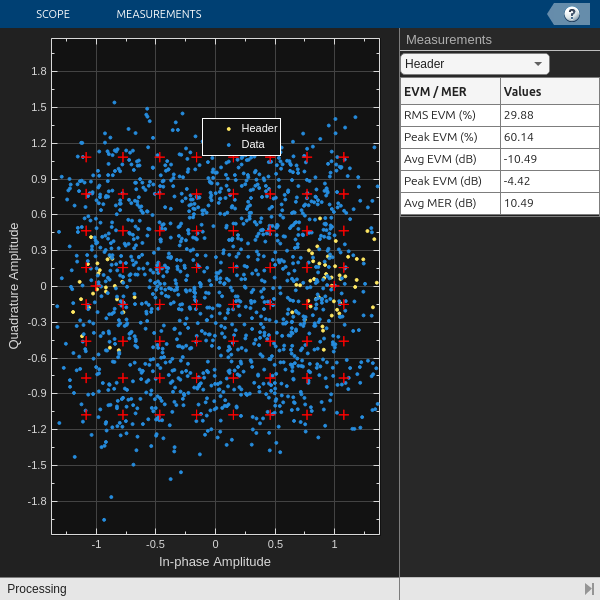

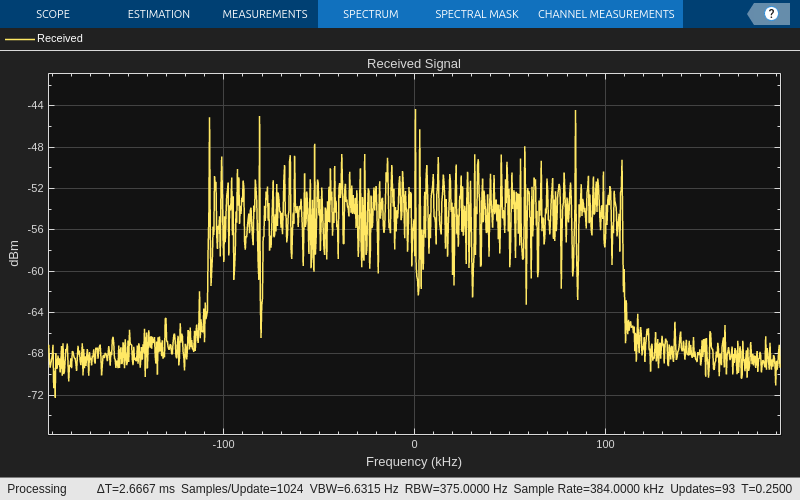

BER = 4.618056e-01 


% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);

for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        else
            BER(frameNum) = 0.5;
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                 complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
    fprintf('BER = %d \n',BER(frameNum));
end

% Display the mean BER value across all frames
for ii = 1:dataParams.numFrames
    if BER(ii) ~= 0.5
        index = ii;
        break;
    end
end
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))

Simulation complete!
Average BER = 4.557908e-01

### SNR ESTIMATION

%Enable properties of the spectrum analyzer
res = getSpectrumData(spectrumAnalyze);
freq = cell2mat(res.FrequencyVector);
spectrum = cell2mat(res.Spectrum);
fmin = -100e3;
idx = (freq >= fmin) & (freq <= fmin*(-1));
meanPowerdB = mean(spectrum(idx));
idx = find(freq == 129000);
SNRestimation = meanPowerdB - (spectrum(idx));
SNR_vect = repmat(SNRestimation, 1, dataParams.numFrames);
fprintf('SNR estimated: %d\n', SNRestimation);

SNR estimated: 1.242524e+01


class = helperPredictionSVM(SNR_vect', BER', SVMModel);
disp(class);

     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



release(radio);

## Troubleshooting

#### **No data in any frame**

Problem

- The receiver continuously receives no data in any frame.

Possible causes

- Transmitter is not running

- Too high or too low transmitter and receiver gains

- Too many under-runs at the transmitter

Possible solutions

- Ensure that the transmitter is running

- Adjust the transmitter and receiver gains

- Adjust the frame length to make sure there are very few under-runs at the transmitter.

#### **Header CRC fails**

Problem

- Even when synchronization and receiver camping are successful, the header CRC check fails.

Possible causes

-  Insufficient compensation of clock frequency offset.

Possible solutions

- The frequency compensation algorithm measures and corrects the frequency and phase offset for each frame, and it can estimate the correct offset up to half of the subcarrier spacing. You can calibrate the frequency offset to resolve this error.

For USRP radios, you can determine the frequency offset by sending a tone at a known frequency from the transmitter and measure the offset between the transmitted and received frequency. Apply the measured offset to the center frequency of `comm.SDRuReceiver` receiver System object.

For ADALM-Pluto radios, run the [Frequency offset calibration with ADALM-Pluto Radio in Simulink](docid:plutoradio_ug#mw_baa863fb-d239-4495-baf9-eb6864e0f592) example to get the frequency offset. Apply the measured offset to the center frequency of the `comm.SDRRxPluto`  receiver System object.

#### **Data decoding fails**

Problem

- The data decoding fails even when the header CRC decoding is successful.

Possible causes

- Data overflow at the receiver

- Inaccurate channel estimate due to exceeding frame length.

Possible solutions

-  Adjust the frame size

- Change the number of symbols per frame to minimize the frame length.